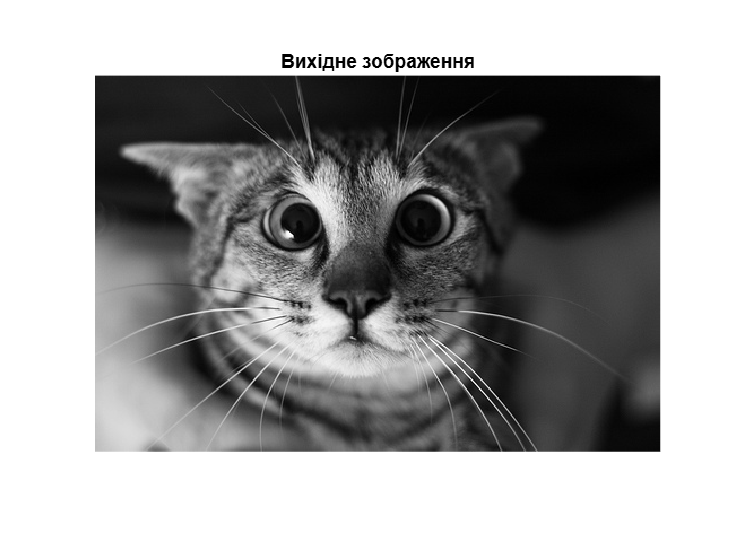

% 1. Завантажити з бібліотеки MATLAB тестове зображення.
% 2. Відобразити вихідні зображення на екрані ПК.
I = imread('cat.jpg');
figure;
imshow(I);
title('Вихідне зображення');

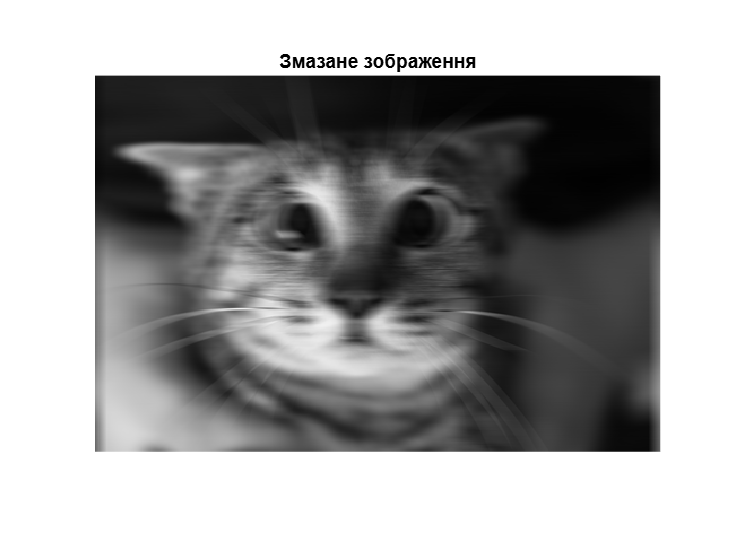

% 3. Здійснити процедуру перекручення зображення змінюючи параметри LEN і THETA.
% 4. Відобразити перекручене зображення.
LEN = 21;
THETA = 0;
PSF = fspecial('motion', LEN, THETA);
blurred = imfilter(I, PSF, 'conv', 'circular');

figure;
imshow(blurred);
title('Змазане зображення');

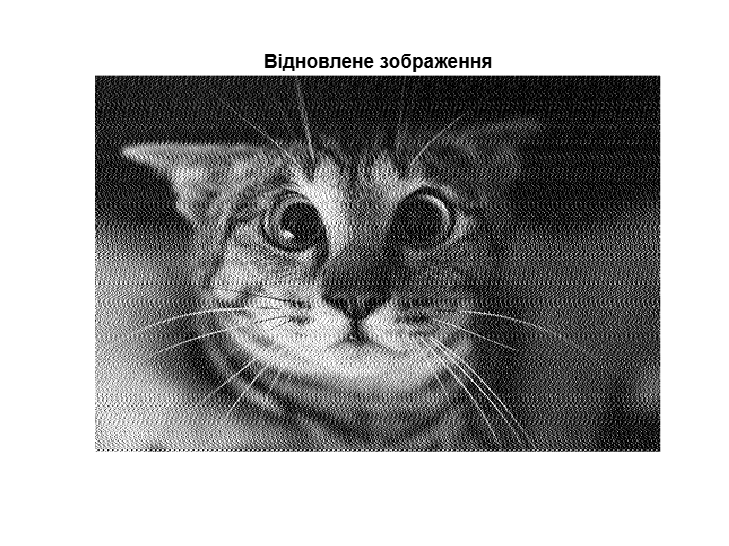

% 5. Виконати процедуру відновлення зображення.
% 6. Відобразити зображення після відновлення.

wnr1 = deconvwnr(blurred, PSF, 0);

figure;
imshow(wnr1);
title('Відновлене зображення');

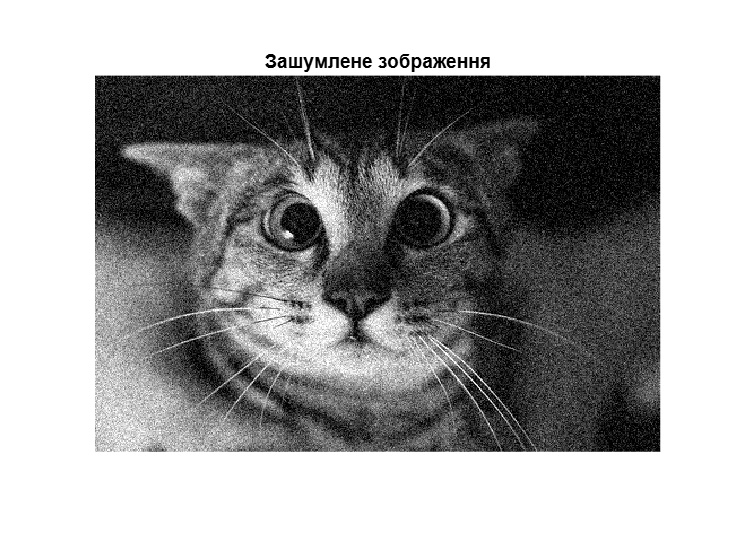

% 7. Виконати зашумлення початкового зображення та повторити пункти 2-6.
noisy = imnoise(I, 'gaussian', 0, 0.01);
figure;
imshow(noisy);
title('Зашумлене зображення');

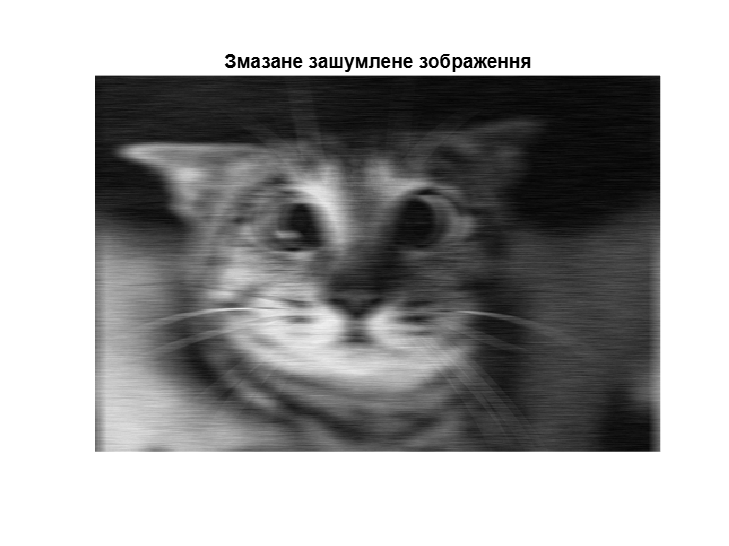

LEN = 21;
THETA = 0;
PSF = fspecial('motion', LEN, THETA);
blurred = imfilter(noisy, PSF, 'conv', 'circular');

figure;
imshow(blurred);
title('Змазане зашумлене зображення')

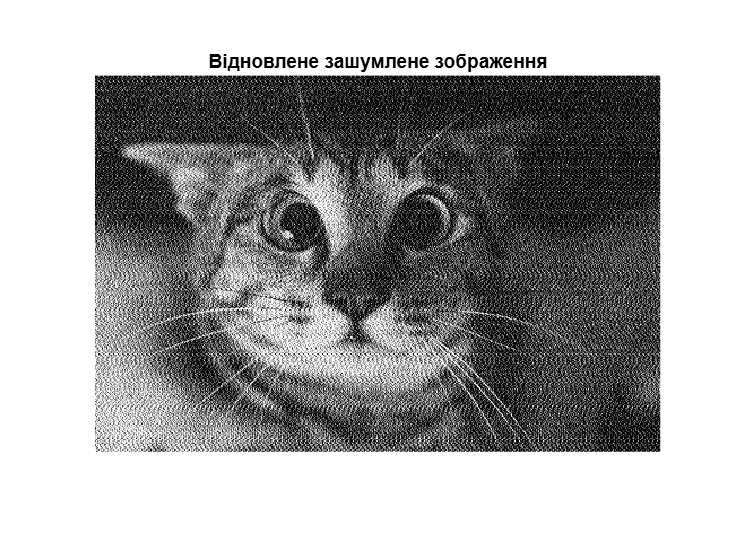


wnr1 = deconvwnr(blurred, PSF, 0);
figure, imshow(wnr1), title('Відновлене зашумлене зображення');